# t_installSegmentation

Illustrates how to align the inplane volume from an fMRI session to the 3D volume anatomy using sample data set [erniePRF](erniePRF)

Dependencies: Remote Data Toolbox

This tutorial is part of a sequence. Run t_initAnatomyFromFreesurfer t_initVistaSession t_alignInplaneToVolume prior to running this tutorial. 

Summary

- Install gray/white segmentation from class file

- Visualize a gray matter ROI

Tested 07/21/2016 - MATLAB r2015a, Mac OS 10.11.6 

Tested 10/03/2018 - MATLAB r2017b, Mac OS 10.13.6

`See also: ``t_initAnatomyFromFreesurfer` `t_initVistaSession` `t_alignInplaneToVolume`

Winawer lab (NYU)

## Start

Clean start in case we have a vista session open

mrvCleanWorkspace();

% Remember where we are
curdir = pwd();

## Organize functional data

% Find ernie PRF session in scratch directory
erniePathTemp      = fullfile(vistaRootPath, 'local', 'scratch', 'erniePRF');

if ~exist(erniePathTemp, 'dir')
    help(mfilename)
    error('Please run  pre-requisite tutorials')
end

% Navigate and create a directory
cd(erniePathTemp)

## Install gray/white segmentation from class file

% Open a hidden view
vw = initHiddenInplane();

Initializing HIDDEN Inplane view
[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [80.000,104.000,12.000] pix.



% Segmentation inputs
%   use command line, not dialog
query = false;       

%   keep all gray nodes, including those outside functional FOV
keepAllNodes = true; 

%   path to class file
filePaths = fullfile('3DAnatomy', 't1_class.nii.gz');

%   number of layers in gray graph along surface (3 layers for 1 mm voxels)
numGrayLayers = 3;

% Do it
installSegmentation(query, keepAllNodes, filePaths, numGrayLayers);

Closing gray windows
Closing flat windows
[installSegmentation]: Rebuilding Gray coordinates with ALL nodes. 
Initializing HIDDEN Volume view
freq_dim not set correctly in NIFTI header.
phase_dim not set correctly in NIFTI header.
[mrLoad]: mr.voxelSize has length<4: concatenating a "1" to it
[mrLoad]: mr.dims has length<4: concatenating a "1" to it
Building gray graph from: 3DAnatomy/t1_class.nii.gz
freq_dim not set correctly in NIFTI header.
phase_dim not set correctly in NIFTI header.
Growing 3 gray layers...
White matter excluded in the gray graph...
Found >1 GM mesh- keeping the first since it has 199828 nodes, which is > half of all nodes (203574 nodes).
Building gray graph from: 3DAnatomy/t1_class.nii.gz
freq_dim not set correctly in NIFTI header.
phase_dim not set correctly in NIFTI header.
Growing 3 gray layers...
White matter excluded in the gray graph...
Found >1 GM mesh- keeping the first since it has 205843 nodes, which is > half of all nodes (206548 nodes).
freq_dim not s

## Visualize a gray matter ROI in the Inplane view

Initializing Inplane view
Attaching menus
[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [80.000,104.000,12.000] pix.
Attaching popup menus
Attaching sliders
Could not find /Users/jonathanwinawer/matlab/toolboxes/vistasoft/local/scratch/erniePRF/Inplane/userPrefs.mat
Done initializing Inplane view


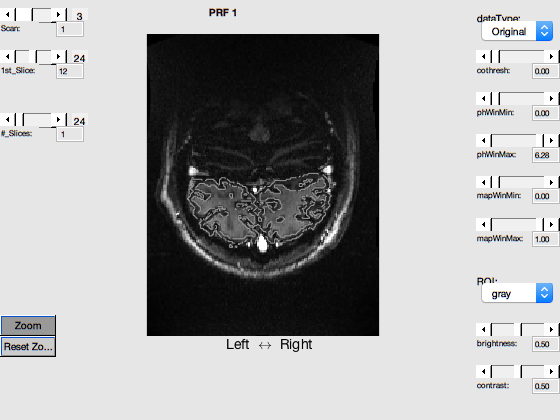

% open a UI
vw = mrVista;


% Define an ROI that is the entire functional slab
vw = makeGrayROI(vw); 

Initializing HIDDEN Gray view
freq_dim not set correctly in NIFTI header.
phase_dim not set correctly in NIFTI header.
[mrLoad]: mr.voxelSize has length<4: concatenating a "1" to it
[mrLoad]: mr.dims has length<4: concatenating a "1" to it
freq_dim not set correctly in NIFTI header.
phase_dim not set correctly in NIFTI header.
[mrLoad]: mr.voxelSize has length<4: concatenating a "1" to it
[mrLoad]: mr.dims has length<4: concatenating a "1" to it
Path to gray coordinates: /Users/jonathanwinawer/matlab/toolboxes/vistasoft/local/scratch/erniePRF/Gray/coords.mat
freq_dim not set correctly in NIFTI header.
phase_dim not set correctly in NIFTI header.
[mrLoad]: mr.voxelSize has length<4: concatenating a "1" to it
[mrLoad]: mr.dims has length<4: concatenating a "1" to it


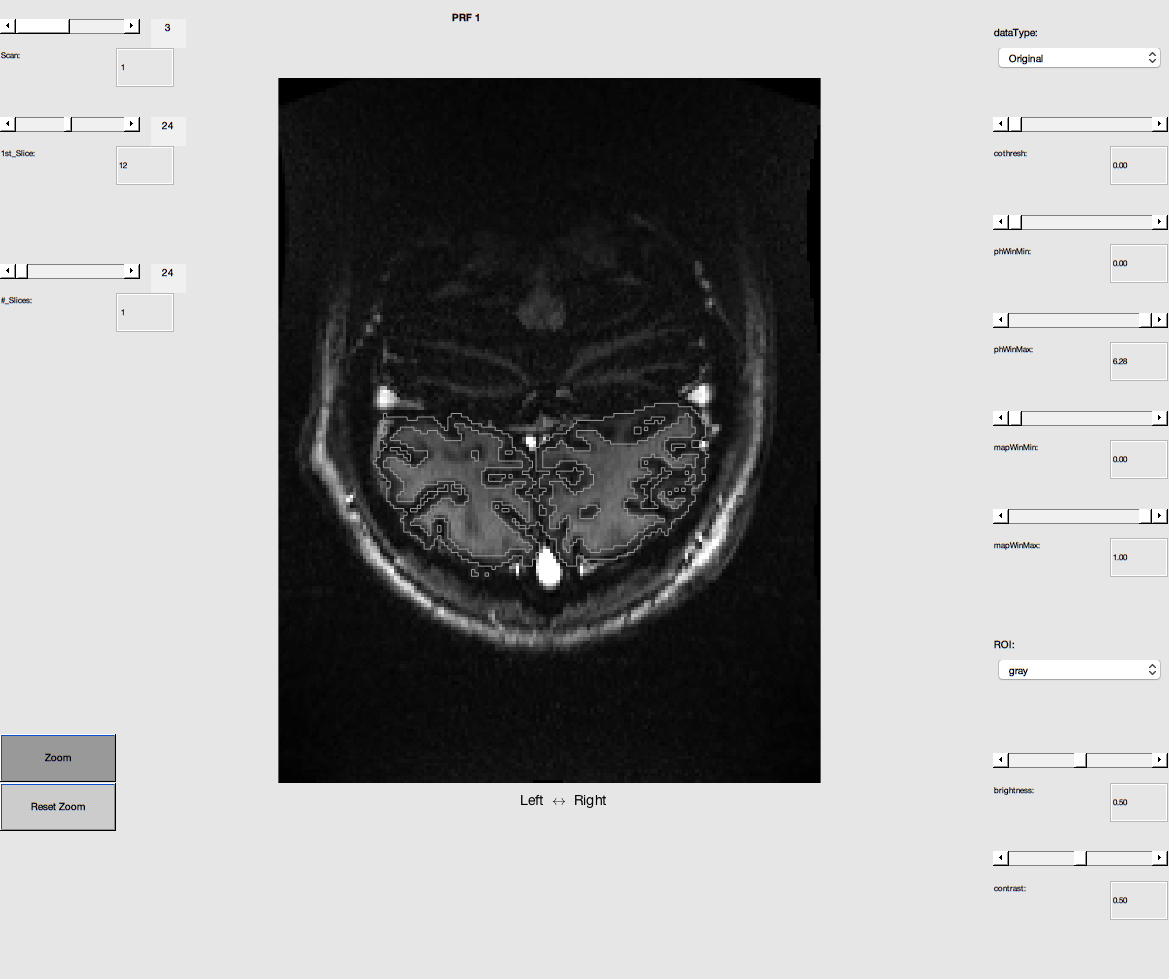

vw = refreshScreen(vw,0);


% add the local variable, vw, to the UI in case you would like to interact
% with the GUI
updateGlobal(vw)

## Clean up

close(viewGet(vw, 'figure number')); 
mrvCleanWorkspace
cd(curdir)